## Plot data and external control signal

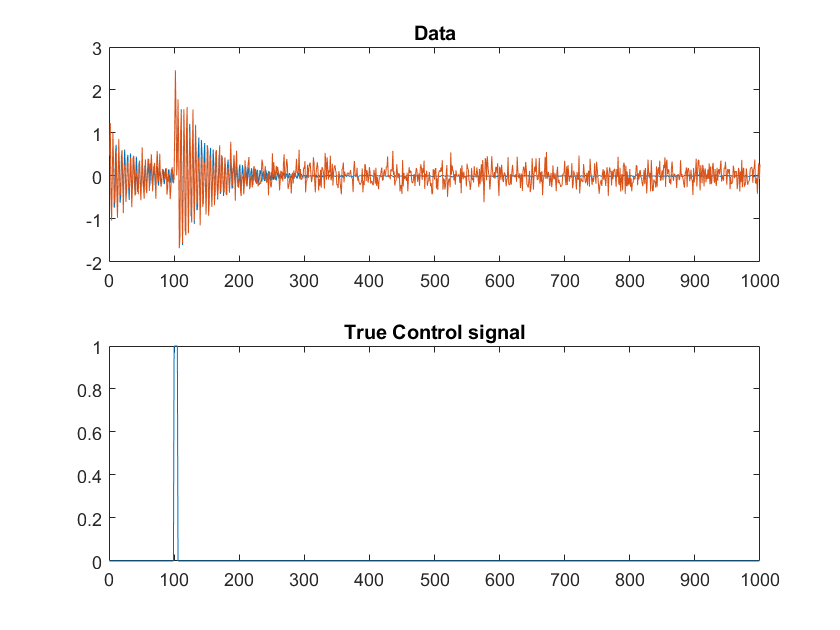

% Build example dynamics matrix
seed = 13;
n = 2;                  % Matrix size; should be even
m = 1000;               % Number of data points
eigenvalue_min = 0.95;  % Minimum eigenvalue; 1.0 = stable
[X_dmd, A] = test_dmd_dat(n, m, 0, eigenvalue_min, seed);

% Build random controller
ctr_timing = 100:105;
U = zeros(1,m-1);
U(ctr_timing) = 1.0;

% Generate controlled data
x0 = X_dmd(:,1);
B = ones(n,1);
X_true = real(calc_reconstruction_dmd(x0, [], A, B, U));
% Add different levels of noise
noise = 0.01;
Xr_low = X_true + noise*randn(size(X_true));
noise = 0.2;
Xr_high = X_true + noise*randn(size(X_true));

% Plot
figure;

subplot(2,1,1)
plot(1:m,Xr_low(1,:))
hold on
plot(1:m, Xr_high(1,:))
title("Data")

subplot(2,1,2)
plot(1:m-1,U)
title("True Control signal")

Time delay embedding!

% We only see one dimension
X = Xr_high(1,:);
num_delays = 2;
X_high = time_delay_embed(X, num_delays);

X = Xr_low(1,:);
X_low = time_delay_embed(X, num_delays);

## Learn the control signal

% Returns a data class with control signals of increasing sparsity
settings = struct('r_ctr',1, ... % Number of control signals to search for
                  'verbose',false, ... 
                   'num_iter',100); % Number of iterations
control_signal_path_low = learn_control_signals(X_low, settings);

All control signals are 0. Stopping early (this is nothing to worry about)


control_signal_path_high = learn_control_signals(X_high, settings);

All control signals are 0. Stopping early (this is nothing to worry about)



% Calculate best control signal
objective_function = 'aic';
control_signal_path_low.calc_best_control_signal(objective_function)

control_signal_path_high.calc_best_control_signal(objective_function)

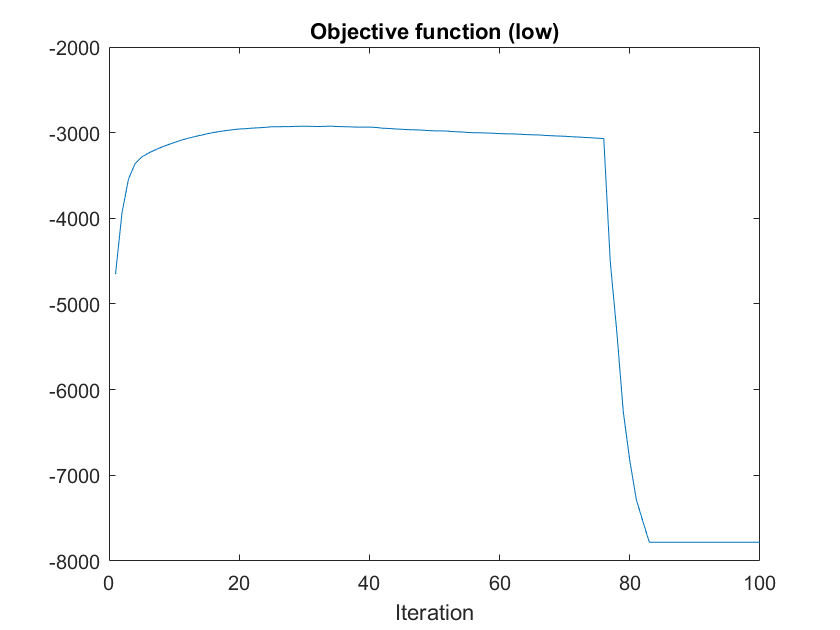


best_U_low = control_signal_path_low.U;
best_U_high = control_signal_path_high.U;

% Plot
objective_vals_low = control_signal_path_low.objective_values;
objective_vals_high = control_signal_path_high.objective_values;

figure;
plot(objective_vals_low)
title('Objective function (low)')
xlabel('Iteration')

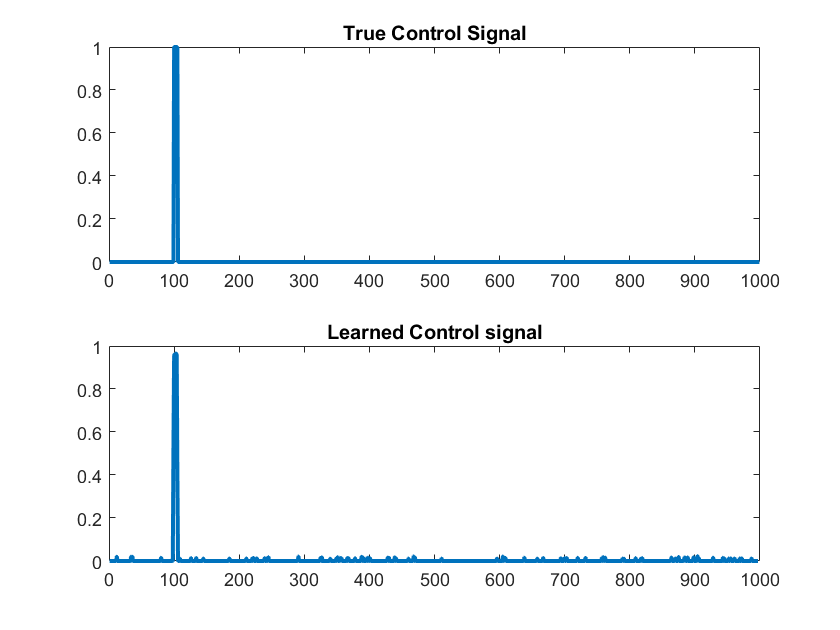


figure;
subplot(2,1,1)
plot(U, 'linewidth', 2)
title("True Control Signal")
subplot(2,1,2)
plot(best_U_low, 'linewidth', 2)
title("Learned Control signal")

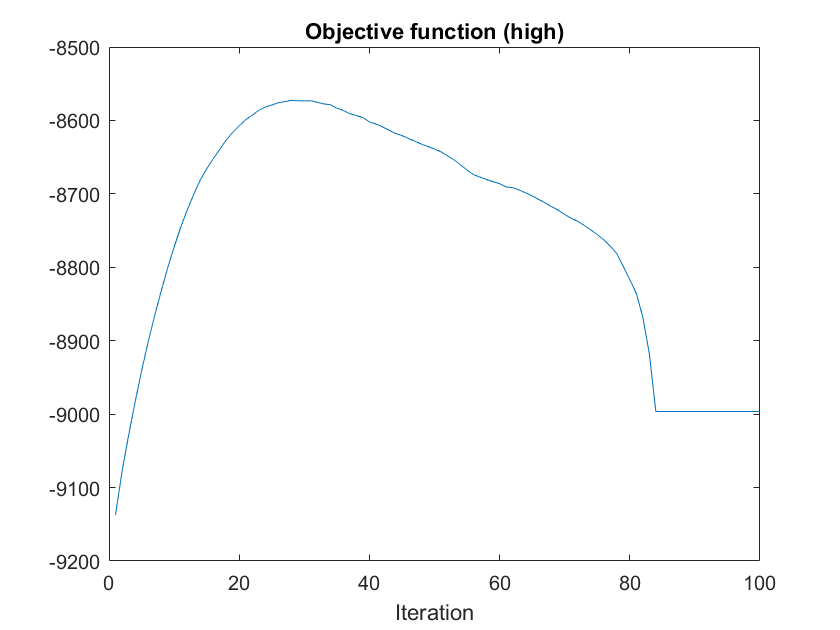



figure;
plot(objective_vals_high)
title('Objective function (high)')
xlabel('Iteration')

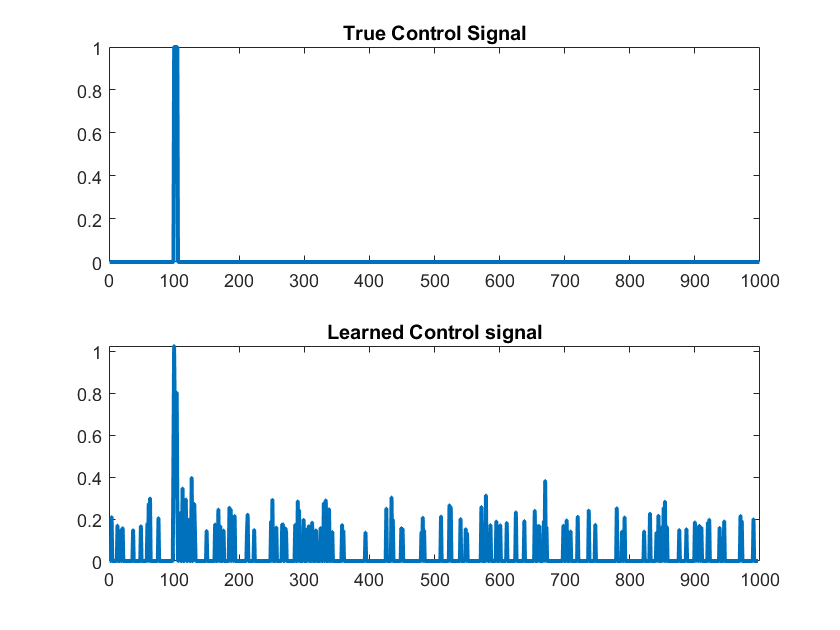


figure;
subplot(2,1,1)
plot(U, 'linewidth', 2)
title("True Control Signal")
subplot(2,1,2)
plot(best_U_high, 'linewidth', 2)
title("Learned Control signal")

## Visualize the frequencies present

% Compare learned and true frequencies
[V, D] = eig(control_signal_path_low.A, 'vector');
[V_true, D_true] = eig(A, 'vector');

figure;
plot(abs(D), angle(D), 'o', 'MarkerSize', 10)
hold on
plot(abs(D_true), angle(D_true), '*', 'MarkerSize', 10)
legend('Learned frequencies', 'True frequencies')
xlim([0, 1])
ylim([0,pi]) % Only display one part of complex conjugate pair
xlabel('Eigenvalue Magnitude (growth or decay)')
ylabel('Eigenvalue Phase (frequency)')
title('Frequencies of the intrinsic dynamics')
